# Parameter Sweep for Reduction Gear Ratio and Battery Size

This script demonstrates a parameter sweep workflow to investigate the effect of reduction gear ratio, high-voltage battery capacity and high-voltage battery weight on the electrical efficiency. Note that this script is configured to finish soon for demonstration purpose.

## Problem Setup

### Drive Cycle & Simulation Configuration

Select drive cycle and whether to use Fast Restart or not. Also select serial simulation with `sim` or parallel simulation with `parsim`. Long drive cycle such as FTP-75 can benefit from parallel simulation, but short drive cycle may not. The number of simulations is another factor to consider. To use `parsim`, Parallel Computing Toolbox is required.

Note that simulation might not be able to complete if parameter set is not properly configuring the vehicle. For example, insufficient reduction gear ratio (i.e., reduced torque performance) with large battery (i.e. heavy weight) can result in a poor performing vehicle setup which might not be able to track the refernece vehicle speed.

driveCycle = "simple_slow_drive_pattern";  % Short drive cycle.
% driveCycle = "ftp75_mph";  % Simulation time is more than 2000 second.

useFastRestart_tf = false;  % Set true or false.
useParsim_tf = false;  % Set true or false.

Show the Simulation Manager or not.

showSimulationManager_onoff = "off";  % 'on' or 'off'

Vehicle model

mdl = "PowerSplitHEV_SpeedTracking";

Signal name of electrical efficiency. The model must have a signal with this name.

elecEffSignalName = "Electrical Efficiency (kW/100km)";

### Grid Points in Sweep Space

Reduction gear ratio

% GearRatio_values = [0.2, 0.23, 0.26, 0.29, 0.32, 0.35];
GearRatio_values = [0.2, 0.28, 0.35];

Capacity and weight of high-voltage battery. They must have the same number of elements.

% nominalCapacity_kWhr_values = [0.5, 1.0, 1.5, 2.0];
% batteryWeight_kg_values     = [110, 125, 140, 155];

nominalCapacity_kWhr_values = [0.5, 1.2, 2.0];
batteryWeight_kg_values     = [100, 115, 130];

### Problem-Related Parameters

Cell voltage

cellVoltage_V = 3.5;  % assuming Li-ion

Initial State-of-Charge (SOC). This can significantly affect the hybrid-driving mode transitions during simulation.

initialSOC_pct = 85;

Component weights. The sum of the following weights and the high-voltage battery weight is the total system weight, which is computed in the Derived Parameters section.

vehicleWeight_kg = 1300;  % Vehicle body, coolant, and oil.
engineFuelWeight_kg = 50*0.75;  % (volume) * (specific gravity)
loadWeight_kg = 70*2;  % Passengers and other goods.

Parameters used in the HEV controller. The followings are just two of them. See `DriverHEVPowerSplit_params.m` for all the parameters.

% SOC value between "mid" and "high" in the HEV controller.
% The controller stops charging high-voltage battery
% if SOC is above this threshold.
highVoltageBatterySoc_HighMidThreshold_pct = 90;

% The HEV controller starts charging high-voltage battery
% if 1) vehicle speed is above this threshold
% and 2) battery charge level is mid or low.
vehicleSpeedThresholdForCharging_kph = 100;

## Derived Parameters

Number of parameter sets

numReductionGearRatioVariations = numel(GearRatio_values)

numReductionGearRatioVariations = 3

numBatterySizeVariations= numel(nominalCapacity_kWhr_values)

numBatterySizeVariations = 3

numParamSets = numBatterySizeVariations*numReductionGearRatioVariations;
disp("Number of parameter sets: " + numParamSets)

Number of parameter sets: 9


Amp-hour rating, i.e., charge, determined from capacity and cell voltage.

nominalCharge_Ahr_values = nominalCapacity_kWhr_values.*1000/cellVoltage_V

nominalCharge_Ahr_values =   142.8571  342.8571  571.4286


Total system weight

systemWeight_kg_values = ...
  vehicleWeight_kg + engineFuelWeight_kg + loadWeight_kg + batteryWeight_kg_values

systemWeight_kg_values = 	1.0e+03 *

    1.5775    1.5925    1.6075


## Build Parameter Sets to Explore

params = struct( ...
  'ID',[], ...
  'gearRatio_1',[], ...
  'nominalCapacity_kWhr',[], ...
  'nominalCharge_Ahr',[], ...
  'batteryWeight_kg',[], ...
  'systemWeight_kg',[], ...
  'initialCharge_Ahr',[] );

[nominalCapacity_kWhr_grid, ~] = meshgrid(nominalCapacity_kWhr_values, GearRatio_values);
[nominalCharge_Ahr_grid, ~] = meshgrid(nominalCharge_Ahr_values, GearRatio_values);
[batteryWeight_kg_grid, ~] = meshgrid(batteryWeight_kg_values, GearRatio_values);
[systemWeight_kg_grid, GearRatio_grid] = meshgrid(systemWeight_kg_values, GearRatio_values);

for paramIdx = 1:numParamSets
  params(paramIdx).ID = "P" + paramIdx;
  params(paramIdx).gearRatio_1 = GearRatio_grid(paramIdx);

  params(paramIdx).nominalCapacity_kWhr = nominalCapacity_kWhr_grid(paramIdx);
  params(paramIdx).nominalCharge_Ahr = nominalCharge_Ahr_grid(paramIdx);
  params(paramIdx).batteryWeight_kg = batteryWeight_kg_grid(paramIdx);
  params(paramIdx).systemWeight_kg = systemWeight_kg_grid(paramIdx);

  params(paramIdx).initialCharge_Ahr = ...
    params(paramIdx).nominalCharge_Ahr * initialSOC_pct/100;
end

Visualize the defined parameter sets. The row names P1, P2, etc. mean Parameter set 1, Parameter set 2, etc.

paramTbl = struct2table(params);
paramTbl.Properties.RowNames = paramTbl.ID;
paramTbl.ID = [];
disp(paramTbl)

          gearRatio_1    nominalCapacity_kWhr    nominalCharge_Ahr    batteryWeight_kg    systemWeight_kg    initialCharge_Ahr
          ___________    ____________________    _________________    ________________    _______________    _________________

    P1        0.2                0.5                  142.86                100               1577.5              121.43      
    P2       0.28                0.5                  142.86                100               1577.5              121.43      
    P3       0.35                0.5                  142.86                100               1577.5              121.43      
    P4        0.2                1.2                  342.86                115             

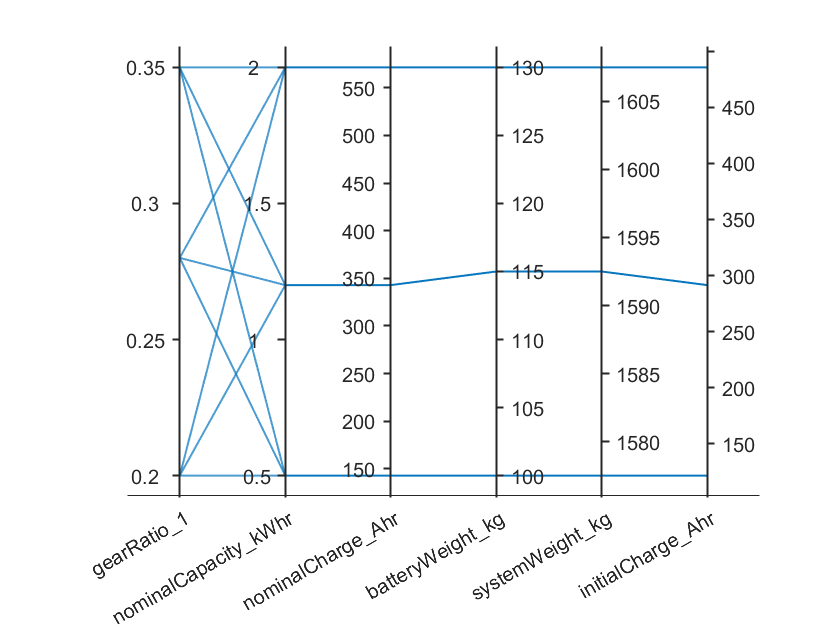

figure
parallelplot(paramTbl, Jitter=0);

## Simulation Setup

To run multiple simulations efficiently, Fast Restart is used. Fast Restart requires Simscape block parameters to be run-time configurable. For more information on these topics, see the following pages.

- [https://www.mathworks.com/help/simulink/ug/fast-restart-workflow.html](https://www.mathworks.com/help/simulink/ug/fast-restart-workflow.html)

- [https://www.mathworks.com/help/physmod/simscape/ug/about-simscape-run-time-parameters.html](https://www.mathworks.com/help/physmod/simscape/ug/about-simscape-run-time-parameters.html)

### Open model

% Default settings loaded here will be overridden later.
if not(bdIsLoaded(mdl)), load_system(mdl); end

Selecting accelerate_decelerate_kph (input_pattern workspace variable)


### Setup Solver

Use the Normal simulation mode with the DAESSC variable-step solver. Fast Restart requires these settings to be saved in the model file before running simulation.

set_param(mdl, SimulationMode="normal");

set_param(mdl, ...
  SolverType = "Variable-step", ...
  SolverName = "daessc", ...
  DaesscMode = "Fast", ...
  RelTol="1e-3", AbsTol="1e-3", AutoScaleAbsTol="off" );

switch useFastRestart_tf
case true
  set_param(mdl, FastRestart="on")
end

save_system(mdl)

### Load Variables in Base Workspace

External input - vehicle speed reference

input_pattern = driveCycle;
disp(input_pattern)

simple_slow_drive_pattern


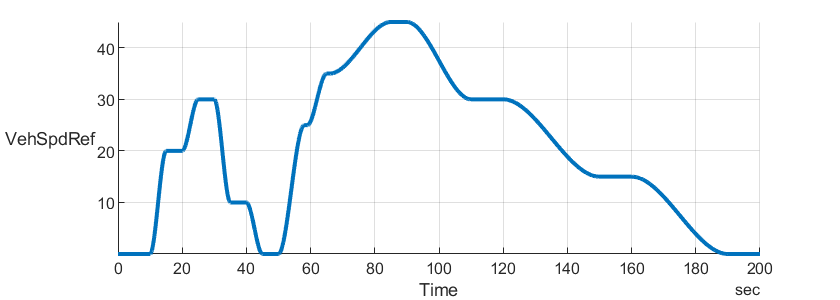

fig = figure;
[inputSignals_DrivingPattern, inputBus_DrivingPattern, initial_DrvPtn, opt1] = ...
  DrivingPatternBasic_inputs( PlotParent=fig, PlotSpeedOnly=true, ...
    InputPattern=input_pattern );
fig.Position(4) = 200;  % height

drivingPattern.useFromWorkspace_tf = opt1.useFromWorkspace;

External input - road grade (flat surface)

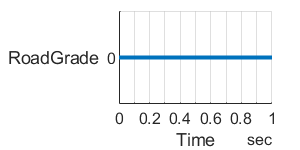

fig = figure;
[inputSignals_RoadGrade, inputBus_RoadGrade, opt2] = ...
  DriverAndEnvironment_road_grade_pattern( PlotParent=fig, InputPattern="flat" );
fig.Position(3:4) = [200 100];  % width height

Simulation time

t_end = max(opt1.t_end, opt2.t_end);

% For the Drive Cycle Source block.
dt = 0;  % 0 for variable-step solver

Default block parameters. Some of these are overridden by Simulation Input objects.

% Plant
PowerSplitHEV_params;

% Controller/Driver - load this after plant
HEVPowerSplitControl_params;

### Build Simulation Input Objects

in(1:numParamSets) = Simulink.SimulationInput(mdl);
for paramIdx = 1 : numParamSets
  in(paramIdx) = setModelParameter(in(paramIdx), "StopTime",num2str(t_end));

  in(paramIdx) = setVariable(in(paramIdx), "initial.highVoltageBatterySOC_pct", initialSOC_pct);

  in(paramIdx) = setVariable(in(paramIdx), "hevcontrol.hvbattSocHighMid_pct", ...
                                  highVoltageBatterySoc_HighMidThreshold_pct);

  in(paramIdx) = setVariable(in(paramIdx), "hevcontrol.chgSpd_kph", vehicleSpeedThresholdForCharging_kph);

  % Reduction gear ratio
  in(paramIdx) = setVariable(in(paramIdx), "powerSplit.reducer_differentialGearRatio", params(paramIdx).gearRatio_1);

  % Battery nominal charge (in controller)
  in(paramIdx) = setVariable(in(paramIdx), "hevcontrol.hvbattNominalCapacity_Ahr", params(paramIdx).nominalCharge_Ahr);

  % Battery initial charge (in plant)
  in(paramIdx) = setVariable(in(paramIdx), "initial.hvBatteryCapacity_Ahr", params(paramIdx).initialCharge_Ahr);

  % Battery initial SOC (in plant)
  in(paramIdx) = setVariable(in(paramIdx), "initial.highVoltageBatterySOC_pct", initialSOC_pct);

  % Battery initial SOC (in controller)
  in(paramIdx) = setVariable(in(paramIdx), "initial.driverHVBattSOC_pct", initialSOC_pct);

  % System weight
  in(paramIdx) = setVariable(in(paramIdx), "vehicle.mass_kg", params(paramIdx).systemWeight_kg);
end

## Run Simulations

Note that total simulation time strongly depends not only on serial or parallel simulation but also on the drive cycle and computer power. For example, in a typical desktop PC with 6 cores, parsim for FTP-75 drive cycle can take 4 minutes or more.

switch useParsim_tf
case true
  tic
  out = parsim(in, ShowSimulationManager=showSimulationManager_onoff);
  toc
otherwise
  tic
  out = sim(in, ShowSimulationManager=showSimulationManager_onoff);
  toc
end

[18-Feb-2022 14:24:51] Running simulations...
[18-Feb-2022 14:24:59] Completed 1 of 9 simulation runs
[18-Feb-2022 14:25:04] Completed 2 of 9 simulation runs
[18-Feb-2022 14:25:09] Completed 3 of 9 simulation runs
[18-Feb-2022 14:25:15] Completed 4 of 9 simulation runs
[18-Feb-2022 14:25:20] Completed 5 of 9 simulation runs
[18-Feb-2022 14:25:25] Completed 6 of 9 simulation runs
[18-Feb-2022 14:25:31] Completed 7 of 9 simulation runs
[18-Feb-2022 14:25:36] Completed 8 of 9 simulation runs
[18-Feb-2022 14:25:41] Completed 9 of 9 simulation runs


Elapsed time is 50.361606 seconds.


Fast Restart is turned off after simulation finished so that the model is editable.

switch useFastRestart_tf
case true
  set_param(mdl, FastRestart="off")
  save_system(mdl)
end

## Process and Visualize Results

Collect simulation results.

result_struct = struct( ...
  'ID',[], ...
  'ElapsedTime',[], ...
  'SpeedUp',[], ...
  'ElectricalEfficiency_kWper100km',[]);

for paramIdx = 1 : numParamSets
  result_struct(paramIdx).ID = "P" + paramIdx;

  t_elapsed = out(paramIdx).SimulationMetadata.TimingInfo.TotalElapsedWallTime;
  result_struct(paramIdx).ElapsedTime = t_elapsed;
  result_struct(paramIdx).SpeedUp = t_end / t_elapsed;

  tmp_sig = out(paramIdx).logsout.get(elecEffSignalName).Values;  % *.Time, *.Data
  result_struct(paramIdx).ElectricalEfficiency_kWper100km = mean(tmp_sig.Data);
end

View the results in table.

resultTbl = struct2table(result_struct);
resultTbl.Properties.RowNames = resultTbl.ID;
resultTbl.ID = [];
disp(resultTbl)

          ElapsedTime    SpeedUp    ElectricalEfficiency_kWper100km
          ___________    _______    _______________________________

    P1      7.9261       25.233                 627.14             
    P2       5.194       38.506                 650.44             
    P3      5.0552       39.563                 655.42             
    P4      5.4181       36.913                  604.8             
    P5      5.3105       37.661                 647.78             
    P6      5.2013       38.452                  665.2             
    P7      5.0561       39.556                 636.59             
    P8       5.165       38.722                 643.63             
    P9      5.1232       39.038                 666.37          

Average speed up of all simulation runs

mean(resultTbl.SpeedUp)

ans = 37.0716

Build a table containing the parameters sets and the corresponding results.

sweepTbl = paramTbl(:, ["gearRatio_1", "nominalCapacity_kWhr", "batteryWeight_kg"]);
elecEffTbl = resultTbl(:, "ElectricalEfficiency_kWper100km");
combinedTbl = join(sweepTbl, elecEffTbl, Keys="Row");

Sort the results based on the efficiency.

[sortedCombinedTbl, sortedIdx] = sortrows(combinedTbl, "ElectricalEfficiency_kWper100km", "ascend");
disp(head(sortedCombinedTbl, min(numParamSets,5)))

          gearRatio_1    nominalCapacity_kWhr    batteryWeight_kg    ElectricalEfficiency_kWper100km
          ___________    ____________________    ________________    _______________________________

    P4        0.2                1.2                   115                        604.8             
    P1        0.2                0.5                   100                       627.14             
    P7        0.2                  2                   130                       636.59             
    P8       0.28                  2                   130                       643.63             
    P5       0.28                1.2                   115                       647.78             



clear Ranking
Ranking(1:numParamSets, 1) = "Other";
Ranking(1) = "Best";
if numParamSets >= 2, Ranking(2) = "2nd Best"; end
% if numParamSets >= 3, Ranking(3) = "3rd Best"; end
rankingTbl = table(Ranking, 'RowNames', "P" + sortedIdx);
disp(head(rankingTbl, min(numParamSets,5)))

           Ranking  
          __________

    P4    "Best"    
    P1    "2nd Best"
    P7    "Other"   
    P8    "Other"   
    P5    "Other"   



Show the final results.

rankedCombinedTbl = join(sortedCombinedTbl, rankingTbl, Keys="Row");
disp(rankedCombinedTbl)

          gearRatio_1    nominalCapacity_kWhr    batteryWeight_kg    ElectricalEfficiency_kWper100km     Ranking  
          ___________    ____________________    ________________    _______________________________    __________

    P4        0.2                1.2                   115                        604.8                 "Best"    
    P1        0.2                0.5                   100                       627.14                 "2nd Best"
    P7        0.2                  2                   130                       636.59                 "Other"   
    P8       0.28                  2                   130                       643.63                 "Other"   
    P5       0.28                1.2                  

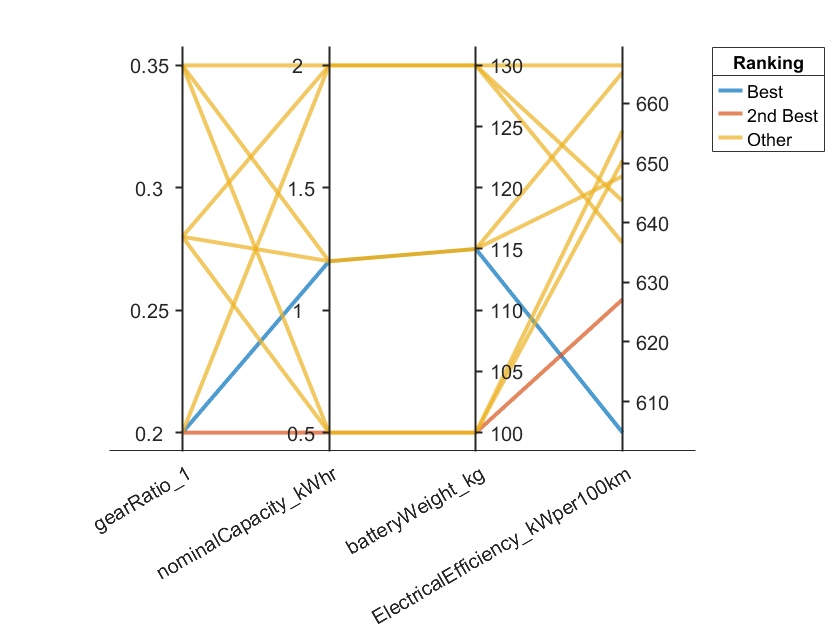

figure
parallelplot(rankedCombinedTbl, ...
  CoordinateVariables = ["gearRatio_1", "nominalCapacity_kWhr",...
    "batteryWeight_kg", "ElectricalEfficiency_kWper100km"],...
  GroupVariable = "Ranking", ...
  Jitter=0, LineWidth=2)

*Copyright 2021-2022 The MathWorks, Inc.*